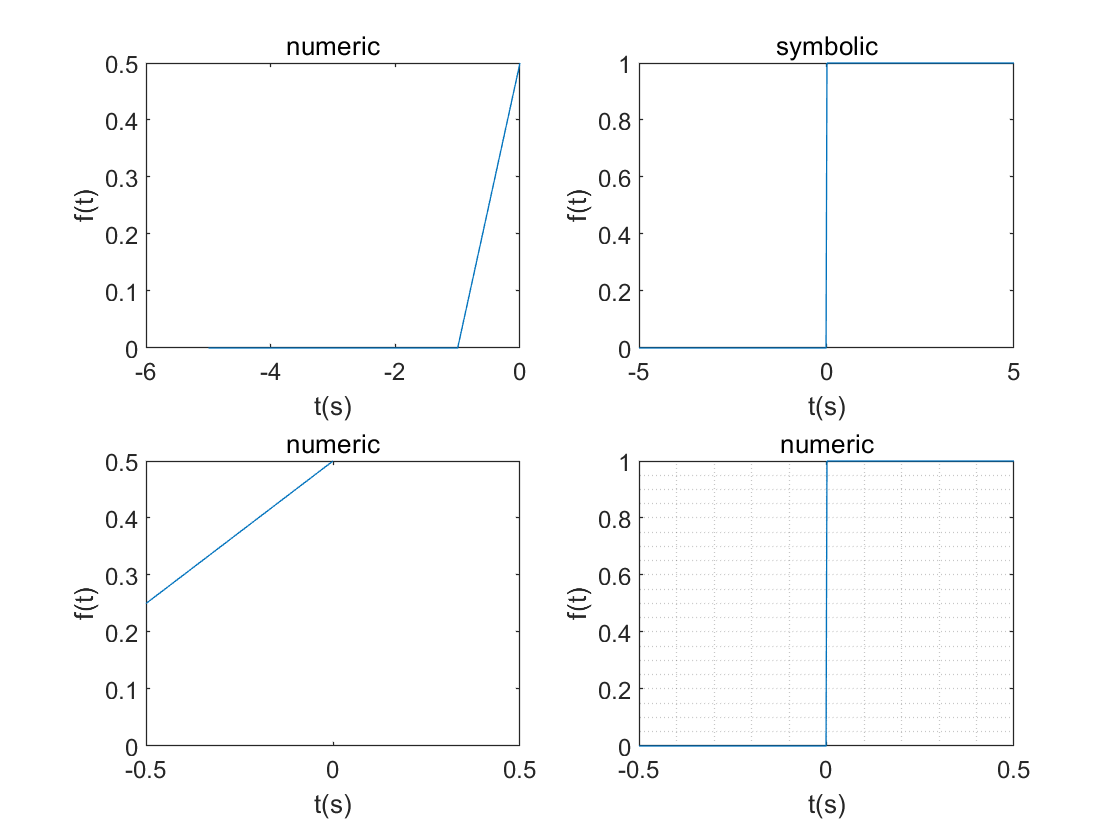

%Step Function
clear;clf;
t = -5:0.1;5;
ft = heaviside(t);

syms x 
y = heaviside(x);

subplot(2,2,1);plot(t,ft);title('numeric');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,2);fplot(x,y);title('symbolic');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,3);plot(t,ft);axis([-0.5 0.5 -inf inf]);title('numeric');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,4);fplot(x,y,[-0.5 0.5]);title('symbolic');xlabel('t(s)');ylabel('f(t)');grid minor;

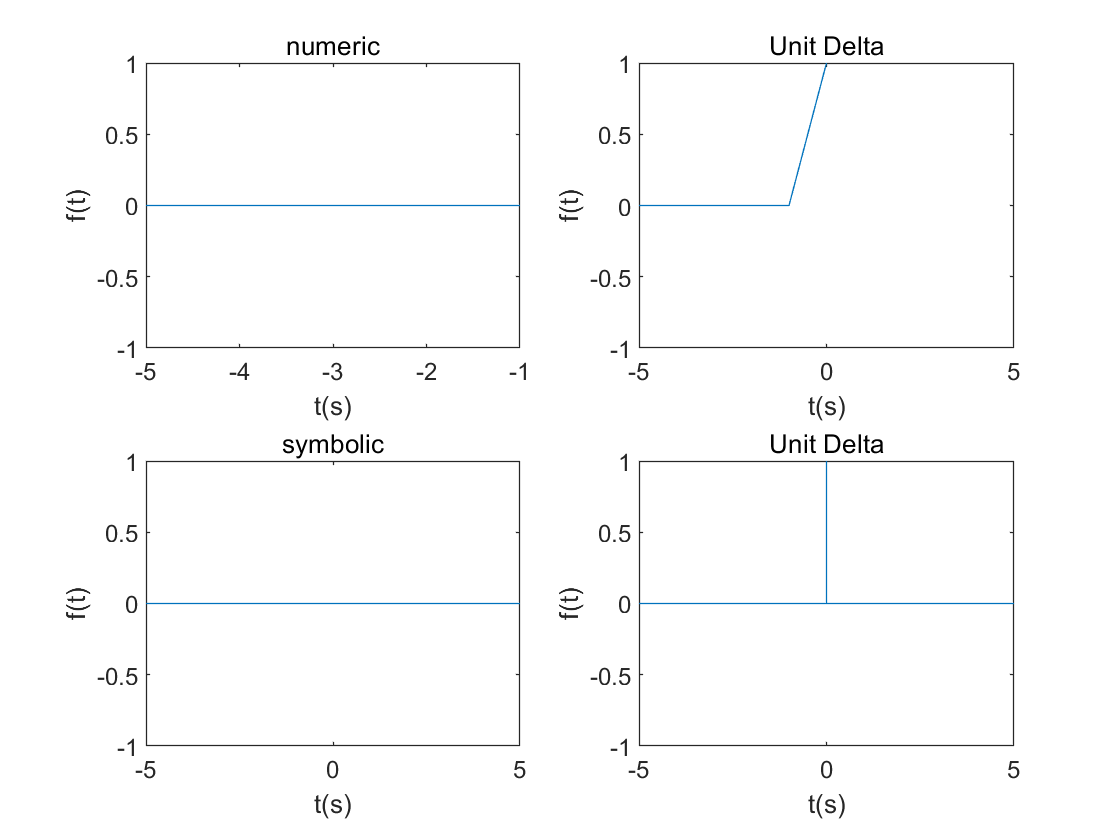

%Delta Function
clear;clf;
t = -5:0.01;5;
ft = dirac(t);

syms x 
y = dirac(x);

subplot(2,2,1);plot(t,ft);title('numeric');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,2);plot(t,sign(ft));axis([-5 5 -1 1]);title('Unit Delta');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,3);fplot(y);title('symbolic');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,4);fplot(sign(y));title('Unit Delta');xlabel('t(s)');ylabel('f(t)');